Features_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v2.csv"; 
Features = readtable(Features_Path);

Features_num = Features;
Features_num.State =[];
Features_num.County = [];

Features_num = table2array(Features_num);

f_mean = mean(Features_num);
Features_num = Features_num - f_mean;

C = cov(Features_num); 
[e,v] = eig(C)

e =    -0.8277    0.2218    0.1909   -0.0413   -0.0765    0.1415    0.2457   -0.3760
   -0.4237    0.0963    0.0390    0.1154    0.1039   -0.6354   -0.3001    0.5401
   -0.0818    0.1323    0.2340   -0.3515   -0.4309    0.5175   -0.3636    0.4602
   -0.3541   -0.5404   -0.6370    0.0915    0.1407    0.3326   -0.1481    0.1269
    0.0374    0.5744   -0.0612    0.4606    0.5030    0.4011   -0.1549    0.1220
   -0.0410   -0.5494    0.7040    0.2921    0.2871    0.1616   -0.0654    0.0511
    0.0063   -0.0117   -0.0317    0.4132   -0.3382    0.0854    0.6949    0.4727
   -0.0168    0.0085    0.0330   -0.6203    0.5728    0.0590    0.4292    0.3131


v =     0.0005         0         0         0         0         0         0         0
         0    0.0020         0         0         0         0         0         0
         0         0    0.0041         0         0         0         0         0
         0         0         0    0.0088         0         0         0         0
         0         0         0         0    0.0104         0         0         0
         0         0         0         0         0    0.0207         0         0
         0         0         0         0         0         0    0.0766         0
         0         0         0         0         0         0         0    0.0935


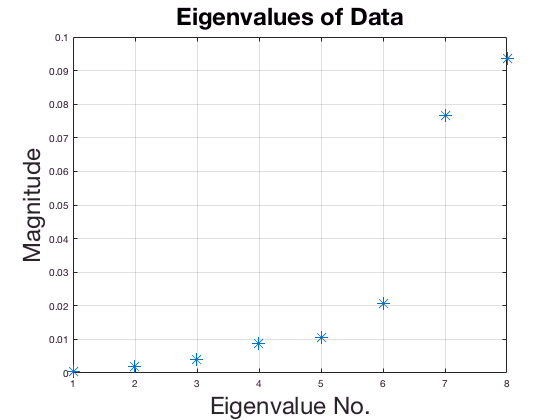


v = diag(v);

plot(v,'*','MarkerSize',12)
grid on
title('Eigenvalues of Data', 'FontSize', 24)
xlabel('Eigenvalue No.', 'FontSize', 24)
ylabel('Magnitude', 'FontSize', 24)


T = e(:,end-1:end); % Transform 
Reduced_Data = Features_num*T

Reduced_Data =    -0.0404   -0.2346
    0.0957   -0.2508
    0.0776   -0.1968
   -0.1034    0.1192
    0.0227   -0.2896
   -0.2480    0.4891
   -0.1063   -0.1625
    0.1168    0.1570
    0.2021    0.4160
   -0.0033   -0.1426


test = Reduced_Data(:,2) > 1

test = 842×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   


plot(Reduced_Data(:,1), Reduced_Data(:,2), '*')

Error using plot
Error in color/linetype argument.

%scatter3(Reduced_Data(:,1), Reduced_Data(:,2), Reduced_Data(:,3))
xlabel('x axis', 'FontSize', 24)
ylabel('y axis', 'FontSize', 24)
title('PCA Reduced Data', 'FontSize', 24)
grid on